fprintf('please Select an image');

please Select an image

y=uigetfile('*.*');
i=imread(y);
k=double(rgb2gray(i));
d = padarray(k,[1 1],0,'both');
[r,c]=size(d);
hori=zeros(r+2,c+2)

hori =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

verti=zeros(r+2,c+2)

verti =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

diag1=zeros(r+2,c+2)

diag1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

diag2=zeros(r+2,c+2)

diag2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

hor=[-1 -1 -1 ; 2 2 2 ; -1 -1 -1 ]

hor =     -1    -1    -1
     2     2     2
    -1    -1    -1


ver=[-1 2 -1 ; -1 2 -1 ; -1 2 -1 ]

ver =     -1     2    -1
    -1     2    -1
    -1     2    -1


dia1=[2 -1 -1 ; -1 2 -1 ; -1 -1 2 ]

dia1 =      2    -1    -1
    -1     2    -1
    -1    -1     2


dia2=[-1 -1 2 ; -1 2 -1 ; 2 -1 -1 ]

dia2 =     -1    -1     2
    -1     2    -1
     2    -1    -1


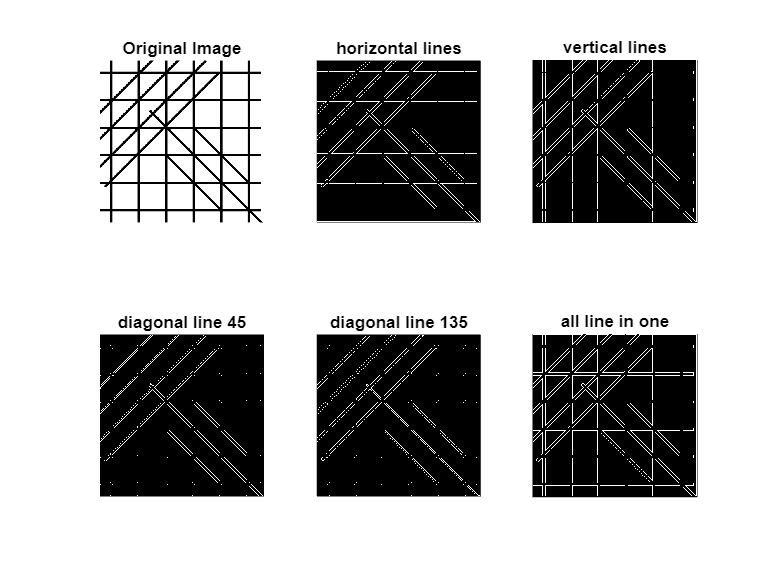

for x =2:(r-1)
   for y=2:(c-1)
      kernel= [d(x-1,y-1) d(x-1,y) d(x-1,y+1) ; d(x,y-1) d(x,y) d(x,y+1) ; d(x+1,y-1) d(x+1,y) d(x+1,y+1)];
      h=sum(sum(hor.*kernel));
      v=sum(sum(ver.*kernel));
      d1=sum(sum(dia1.*kernel));
      d2=sum(sum(dia2.*kernel));
      hori(x,y)=h;
      verti(x,y)=v;
      diag1(x,y)=d1;
      diag2(x,y)=d2;
   end
end
all=hori+verti+diag1+diag2;
subplot(2,3,1);imshow(i);title('Original Image');
subplot(2,3,2);imshow(hori);title('horizontal lines');
subplot(2,3,3);imshow(verti);title('vertical lines');
subplot(2,3,4);imshow(diag1);title('diagonal line 45');
subplot(2,3,5);imshow(diag2);title('diagonal line 135');
subplot(2,3,6);imshow(all);title('all line in one');